# Demo: Visualizing and Analyzing Phased Arrays in MATLAB

In this demo, we will illustrate some basic computations for phased arrays. In doing this demo, you will learn to:

- Add beamforming gain to a link budget

- Create and visualize simple antenna arrays

- Compute steering vectors and array factors

- Plot array patterns in 2D and 3D

- Incorporate element gain into the array

## SNR gain example with RX beamforming

To begin we illustrate the gain in SNR, we consider the following simple example. The example shows that 8 antennas provides a 9 dB SNR gain.

% Parameters
dist = 1000;    % distance (m)
fc = 28e9;      % frequency
lambda = physconst('LightSpeed')/fc;
ptx = 23;       % TX power 
dirtx = 10;     % TX and RX directivity in dBi
dirrx = 5;
Enoise = -170;  % Noise energy (incl NF)
bw = 400e6;     % Bandwidth
nantrx = 8;     % Number of RX antennas

% SNR per antenna assuming free-space path loss
plomni = fspl(dist, lambda);
EsN0Ant = ptx - plomni - 10*log10(bw) - Enoise + dirtx + dirrx; 

% SNR with MRC
EsN0MRC = EsN0Ant + 10*log10(nantrx);

fprintf(1,'SNR per  ant: %7.2f\n', EsN0Ant);

SNR per  ant:    0.59


fprintf(1,'SNR with MRC: %7.2f\n', EsN0MRC);

SNR with MRC:    9.62


## Uniform Linear Array

We first define a simple uniform linear array

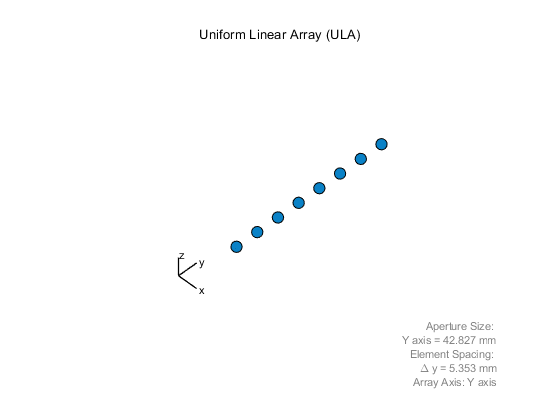

fc = 28e9;           % frequency
lambda = physconst('LightSpeed')/fc;
dsep = 0.5*lambda;   % element spacing
nant = 8;            % Number of elements
arr = phased.ULA(nant,dsep);

% View the array
viewArray(arr,'Title','Uniform Linear Array (ULA)')

## Plotting the array element positions manually

We can also get the positions into an array Note we need the clf('reset') command to clear the figure from viewArray. The phased array toolbox plotting routines screw up all future plots.

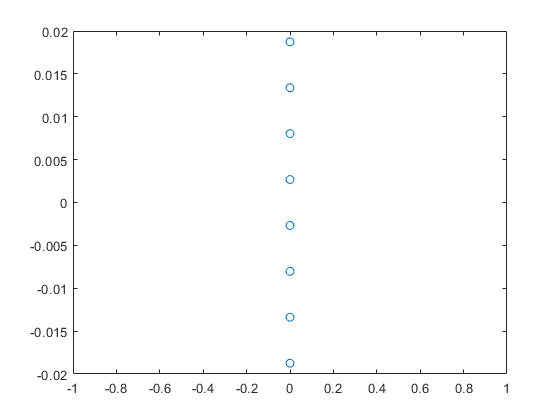

elemPos = arr.getElementPosition();
clf('reset');
plot(elemPos(1,:), elemPos(2,:), 'o');

## Computing the spatial signature

To compute the spatial signature of an array, you can use the following command

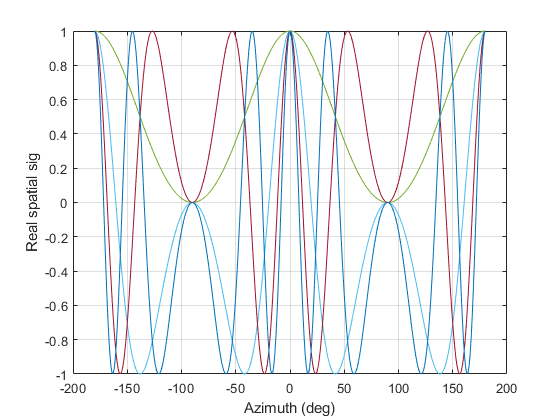

% Create a steering vector object
sv = phased.SteeringVector('SensorArray',arr);

% Angles to compute the SVs
npts = 361;
az = linspace(-180,180,npts);
el = zeros(1,npts);
ang = [az; el];

% Matrix of steering vectors
% This is an nant x npts matrix in this case
u = sv(fc, ang);

% Plot of the real components
plot(az, real(u)');
grid on;
xlabel('Azimuth (deg)')
ylabel('Real spatial sig');

## Uniform Planar Array

We next look at a simple uniform planar array

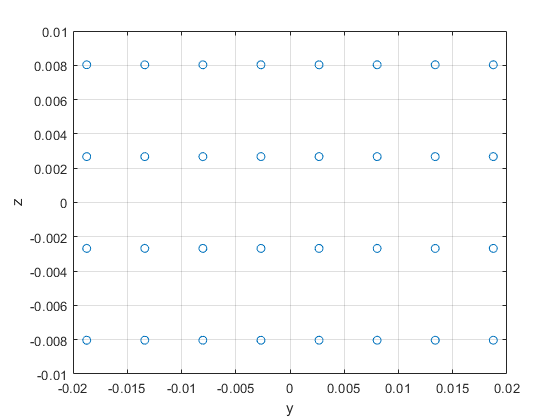

% Construct a URA 
nant = [4,8];
dsep = 0.5*lambda;
arr = phased.URA(nant,dsep,'ArrayNormal','x');

% Plot the array.
% You can also use, arr.viewArray()
elemPos = arr.getElementPosition();
clf('reset');
plot(elemPos(2,:), elemPos(3,:), 'o');
grid on;
xlabel('y');
ylabel('z');

## Manually plotting the 2D array factor

We now show how to plot the array factor

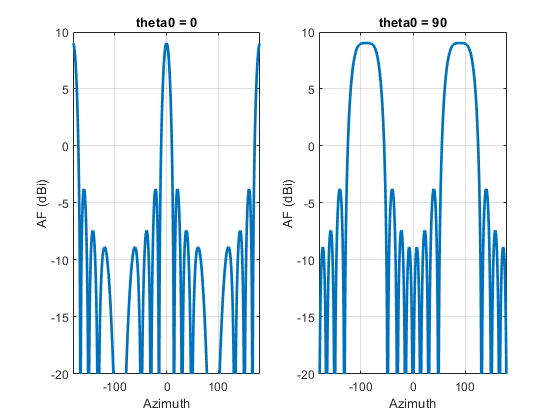

% Create the ULA
nant = 8;            % Number of elements
arr = phased.ULA(nant,dsep);

% Create a steering vector object
sv = phased.SteeringVector('SensorArray',arr);

% Reference angles to plot the AF
azPlot = [0, 90];
nplot = length(azPlot);

for iplot = 1:nplot
    % Get the SV for the beam direction.
    % Note:  You must call release method of the sv 
    % before each call since it expects the same size
    % of the input
    ang0 = [azPlot(iplot); 0];
    sv.release();
    u0 = sv(fc, ang0);
    
    % Normalize the direction
    u0 = u0 / norm(u0);
    
    % Get the SV for the AoAs.  Take el=0
    npts = 1000;
    az = linspace(-180,180,npts);
    el = zeros(1,npts);
    ang = [az; el];
    sv.release();
    u = sv(fc, ang);
    
    % Compute the AF and plot it
    AF = 10*log10( abs(sum(conj(u0).*u, 1)).^2 );
    
    % Plot it
    subplot(1,nplot,iplot);
    plot(ang(1,:), AF, 'LineWidth', 2);
    grid on;
    ylim([-20,10]);
    xlabel('Azimuth');
    ylabel('AF (dBi)');
    xlim([-180,180]);
    
    titleStr = sprintf('theta0 = %d', azPlot(iplot));
    title(titleStr);
    
end

## Polar plot of array factor in 2D

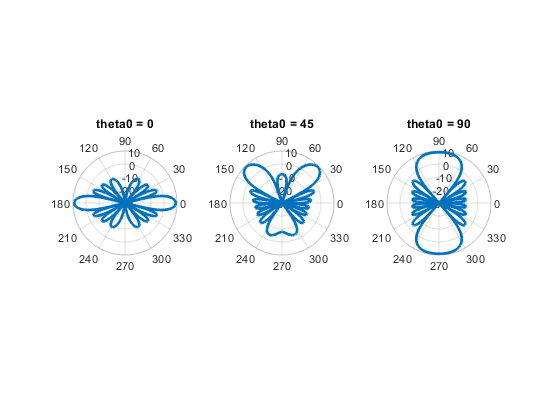

% Create a steering vector object
sv = phased.SteeringVector('SensorArray',arr);

% Reference angles to plot the AF
azPlot = [0, 45, 90];
nplot = length(azPlot);

for iplot = 1:nplot
    % Get the SV for the beam direction.
    % Note:  You must call release method of the sv 
    % before each call since it expects the same size
    % of the input
    ang0 = [azPlot(iplot); 0];
    sv.release();
    u0 = sv(fc, ang0);
    
    % Normalize the direction
    u0 = u0 / norm(u0);
    
    % Get the SV for the AoAs.  Take el=0
    npts = 1000;
    az = linspace(-180,180,npts);
    el = zeros(1,npts);
    ang = [az; el];
    sv.release();
    u = sv(fc, ang);
    
    % Compute the AF and plot it
    AF = 10*log10( abs(sum(conj(u0).*u, 1)).^2 );
        
    % Polar plot
    AFmin = -30;
    subplot(1,nplot,iplot); 
    polarplot(deg2rad(az), max(AF, AFmin),'LineWidth', 2);
    rlim([AFmin, 10]);
    grid on;
    
    titleStr = sprintf('theta0 = %d', azPlot(iplot));
    title(titleStr);
    
end

## Plotting the AF using the in-built function

You can also plot the directivity of the array with MATLAB's built in tool. Note that the directivity will be differ from the AF by a constant since it is normalized to one. Also, you do not have as much flexibility in this plot

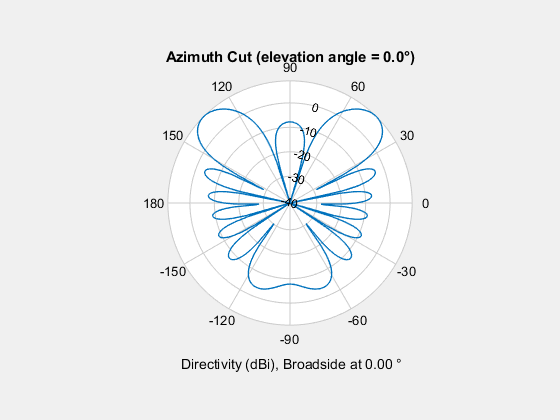

% Parameters
dsep = 0.5*lambda;     % element spacing
nant = 8;            % Number of elements
arr = phased.ULA(nant,dsep);

% Get the SV for the beam direction.
ang0 = [45; 0];
sv.release();
u0 = sv(fc, ang0);
        
% Plot the pattern
subplot(1,1,1);
arr.patternAzimuth(fc, 'Weights', u0);

## Grating lobes

When the antennas are spaced more than lambda/2, we see other lobes where the arry has high gain. These are called grating lobes To illustrate we take d = 2\lambda.

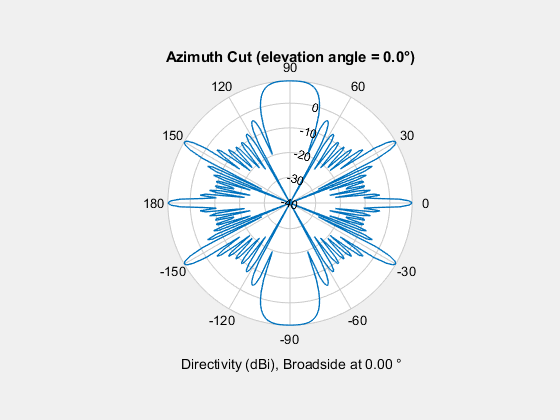

dsep = 2*lambda;     % element spacing
nant = 8;            % Number of elements
arr = phased.ULA(nant,dsep);

% Get the SV for the beam direction.
ang0 = [0; 0];
sv.release();
u0 = sv(fc, ang0);

arr.patternAzimuth(fc,'Weights', u0);

## Plotting the 3D pattern

We can use MATLAB's function to plot the directivity. Again, remember the directivity differs from the AF by a constant factor.

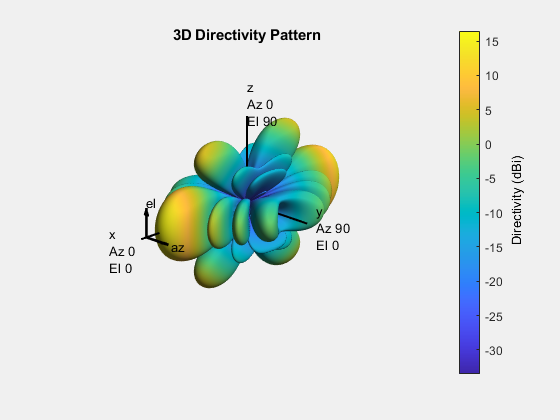

% Construct a URA 
nant = [4,8];
dsep = 0.5*lambda;
arr = phased.URA(nant,dsep,'ArrayNormal','x');

% Compute the beamforming vector
sv = phased.SteeringVector('SensorArray',arr);
ang0 = [0; 0];
sv.release();
u0 = sv(fc, ang0);
u0 = u0 / norm(u0);

% We can plot the directivity in a 3D plot
arr.pattern(fc,'Weights', u0);

We can also plot a 2D plot at a particular elevation angle. This is called a "cut"

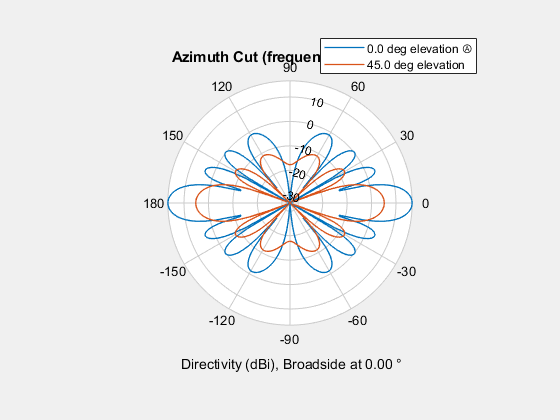

elPlot = [0 45];
arr.patternAzimuth(fc, elPlot, 'Weights', u0);

## Adding the element gain

The above arrays were all isotropic elements. In practice, each element itself has a pattern. This can be included easily in the phased array toolbox. As an example, we add a standard path element and plot the resulting pattern of the array. We see that the element reduces the gain in negative x direction and increases the gain in the positive x direction. 

% Create the patch element
len = 0.49*lambda;
groundPlaneLen = lambda;
ant = patchMicrostrip(...
    'Length', len, 'Width', 1.5*len, ...
    'GroundPlaneLength', groundPlaneLen, ...
    'GroundPlaneWidth', groundPlaneLen, ...
    'Height', 0.01*lambda, ...
    'FeedOffset', [0.25*len 0]);

% Tilt the element so that the maximum energy is in the x-axis
ant.Tilt = 90;
ant.TiltAxis = [0 1 0];

% Build the array including the element
nant = [4,8];
arr2 = phased.URA(nant,dsep,'ArrayNormal','x','Element',ant);

% Plot the pattern of the array with isotropic elements
subplot(2,1,1);
arr.pattern(fc);

% Plot the pattern of the array with patch elements
subplot(2,1,2);
arr2.pattern(fc);

## Visualizing pattern multiplication

The gain in the previous plot can be explained by **pattern multiplication**: In dB scale, the element gain adds to the array gain. To visualize this, we plot the element gain along with the array directivity with isotropic elements and with actual elements.  It should be noted that pattern multiplication is an approximation and ignores mutual coupling.  A more accurate method is shown in the mutualCoupling.mlx demo.

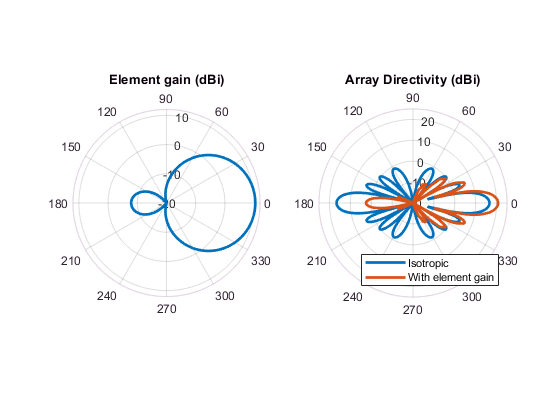

% Get the element gain
elPlot = 0;
az = (-180:180);
dirElem = ant.patternAzimuth(fc, elPlot, 'Azimuth', az);

% Get the directivity with isotropic elements
sv = phased.SteeringVector('SensorArray',arr);
ang0 = [0; 0];
sv.release();
u0 = sv(fc, ang0);
u0 = u0 / norm(u0);
dirIso = arr.patternAzimuth(fc, elPlot, 'Weights', u0, 'Azimuth', az);

% Get the directivity with patch element
dirTotal = arr2.patternAzimuth(fc, elPlot, 'Weights', u0, 'Azimuth', az);

% Plot the element gain
clf('reset');
dirMin = -20;
subplot(1,2,1);
polarplot(deg2rad(az), max(dirElem, dirMin), 'Linewidth', 2);
rlim([dirMin, 12]);
title('Element gain (dBi)');

% Plot the array directivity
subplot(1,2,2);
dirPlot = max(dirMin, [dirIso dirTotal]);
polarplot(deg2rad(az), dirPlot, 'Linewidth', 2);
title('Array Directivity (dBi)');
legend('Isotropic', 'With element gain', 'Location', 'SouthEast');
rlim([dirMin, 25]);